# **DEMO:    **7-dof car,  **Simulate** excitations at MODAL frequencies

## Learning Objectives:

- Explore the car's response when excited by ground excitations at/near the car's MODAL frequencies, and draw conclusions on why a MODAL analysis is an important Mechanical Engineering analysis task.

`Bradley Horton : 08-Aug-2021, bhorton@mathworks.com`

## Background:

In this script we'll load into MATLAB, numeric values for the car's mechanical properies (ie:  mass, stiffness, damping).  We'll look specifically at a parameter set where the damping values are very small .... and then we'll run a series of **simulations** where we excite the car with ground displacements that have frequencies that correspond to the various UNdamped natural(**MODAL**) frequencies of the car.

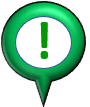 **PAUSE and PONDER:** 

- Do you think it's a BAD idea to excite** a lightly damped **Mechanical system with excitations near/at it's MODAL frequencies ?

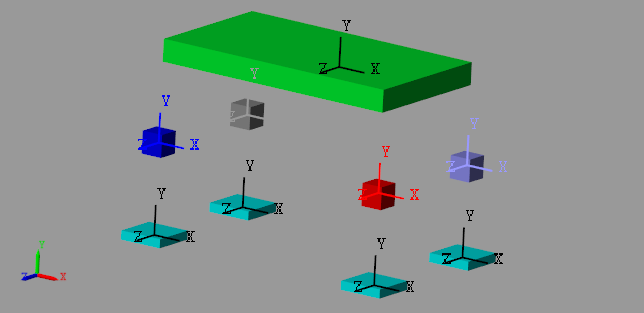  

## Read the car parameters

Our car parameters are defined in  an EXCEL file [`bh_7dof_car_database.xlsx`](matlab:  winopen("bh_7dof_car_database.xlsx"))`.`  The data sheet called **"PARAMS_SET_CLIGHT"** has data where ALL damping co-efficients have(relatively) small values .... so we're looking at a very lightly damped configuration.

OBJ_car_params =  bh_7dof_car_database_CLS("bh_7dof_car_database.xlsx","PARAMS_SET_CLIGHT", "IC_SET_A");

The table below lists the parameters that we'll use in our simulation.  

- **NOTE:** the small values for the damping co-efficients $c_{\textrm{bR}} \;,c_{\textrm{fR}} \;,\;\ldotp \ldotp \ldotp \ldotp c_{\textrm{bRG}} \;,\ldotp \ldotp \ldotp$ etc

OBJ_car_params.car_tab

ans = 29×4 table
              Name       Value      Units                     Description                
             _______    _______    ________    __________________________________________

    m_c      "m_c"         1500    "kg"        "Mass of car body"                        
    I_cZ     "I_cZ"        1000    "kg.m^2"    "Inertia (Z-axis) of car body"            
    I_cX     "I_cX"         600    "kg.m^2"    "Inertia (X-axis) of car body"            
    m_bR     "m_bR"          80    "kg"        "Mass of back RIGHT wheel and suspension" 
    m_fR     "m_fR"         100    "kg"        "Mass of front RIGHT wheel and suspension"
    m_bL     "m_bL"          80    "kg"        "Mass of back LEFT wheel and suspension"  
    m_fL 

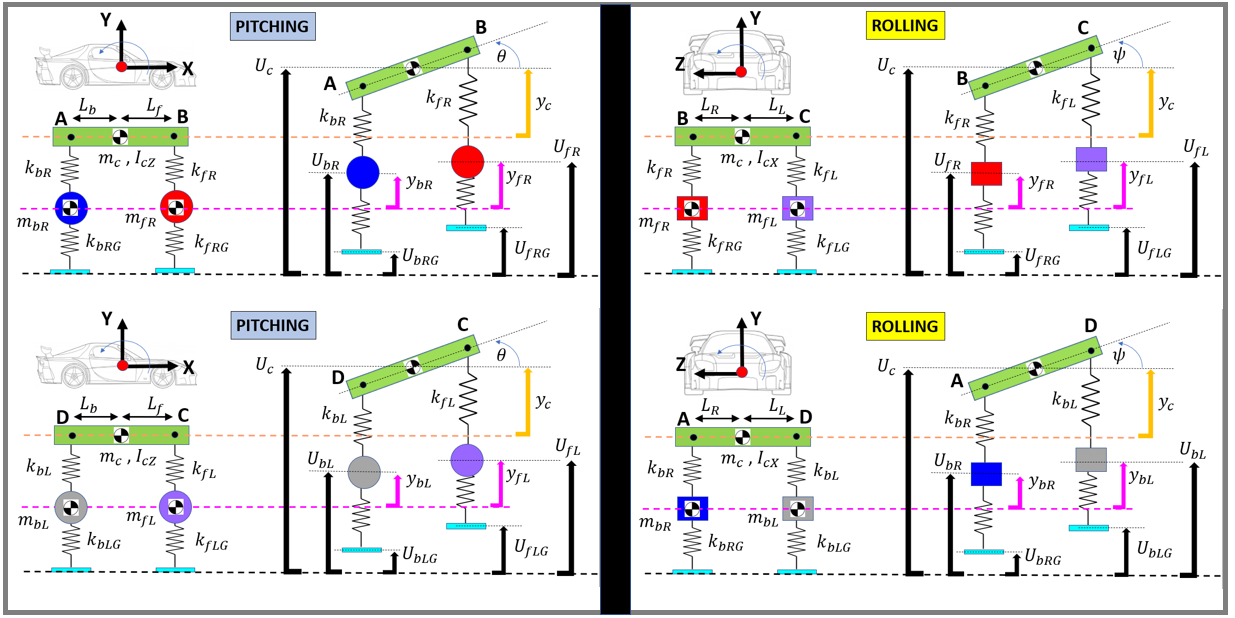

## The Simulation experiments that we'll try:

In a moment we'll open a **Simulink** file that implements our **Brain derived equations of motion** for the 7-dof car - the ODEs in the Simulink file get numerically solved.  Our Simulink file also contains an alternate way of modelling the car using **Simscape Multibody** - we'll **compare** our Brain derived simulation results against the results produced by the Simscape model.  The Simscape model also gives a really nice animation "showing" the car's response in a CAD like viewer.

The main block that we'll interact with during these experiments is shown below - it's a block called **ROAD_SYS_MODAL**

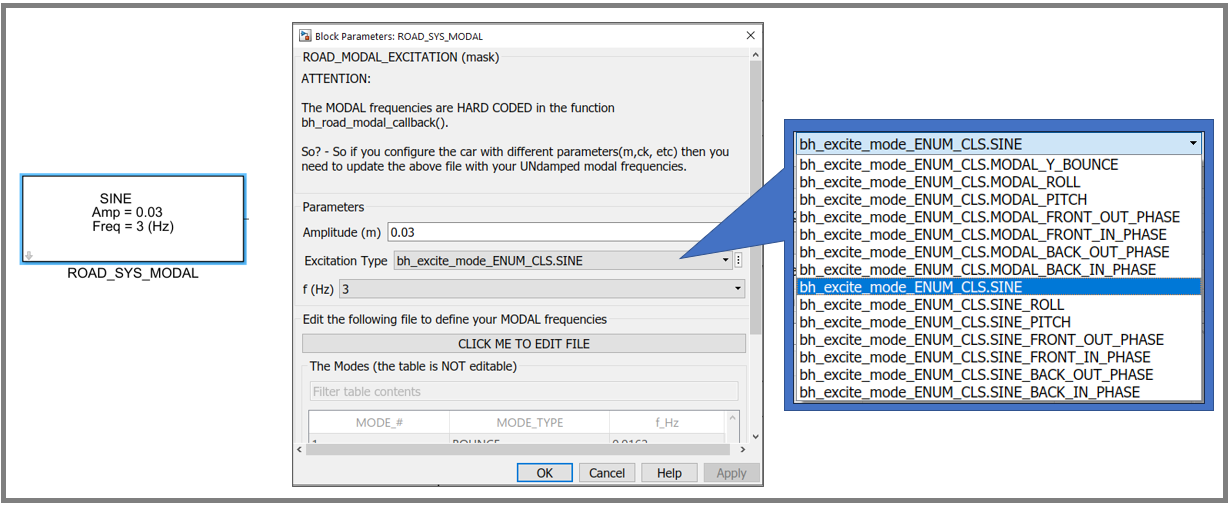

The  **ROAD_SYS_MODAL **block has a dropdown box called "**Excitation Type**" - and the choices are displayed below. So we can choose an Excitation Type that either

- Excites the car at one of it's MODAL frequencies,  OR

- Does NOT excite the car at a modal frequency

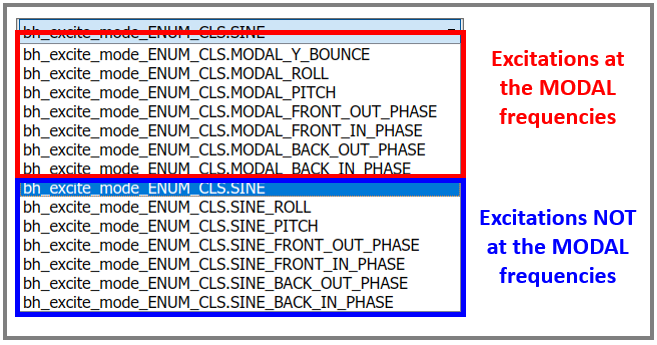

**Experimental steps:  **So the process that we'll follow is outlined below:

- Double click on the** ROAD_SYS_MODAL** block

- Choose a NON-modal Excitation type, eg:    SINE_ROLL

- Run the simulation

- Open the  **MAIN scope block** ... and observe the time responses of our 7-dof $\left\lbrack \begin{array}{ccccccc}
y_c  & \theta  & \psi  & y_{\textrm{bR}}  & y_{\textrm{fR}}  & y_{\textrm{bL}}  & y_{\textrm{fL}} 
\end{array}\right\rbrack$ AND also the 4 -ground displacements $\left(U_{\textrm{bR}} \;\;,U_{\textrm{fR}} \;,U_{\textrm{bL}} \;,U_{\textrm{fL}} \right)\;\;$ 

- The Simscape CAD view will also appear showing an animation of the car's response

- Now choose the corresponding MODAL Excitation, eg:  MODAL_ROLL and repeats steps 3-5

These experiments should help you answer the question posed at the start of this script, ie:

- ***Do you think it's a BAD idea to excite a lightly damped Mechanical system with excitations near/at it's MODAL frequencies ?***

## Open the Simulink file and conduct the experiments described above

open_system("bh_SIM_7dof_car_MODAL_excite.slx")